# Maximizing Solar Panel Output for a Fixed Area

Given a fixed area, determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output.

**Contraints: **

Area: $2m^2$

Tilt Angle(in degrees): $0\le \theta \le 90$

Aspect Ratio: $0\ldotp 5\le r\le 4$

## Break Down the Problem

**Problem Statement:**

Given a fixed area, find the optimal angle and optimal aspect ratio that outputs the maximum energy. 

**Requirements/Constraints:**

- Fixed area = $2m^2$

- theta(tilt angle in degrees) = $0\le \theta \le 90$

- r (aspect ratio of length / width)$=\;0\ldotp 5\le r\le 4$

- Panel must have geometry of rectangle to not complicate geometry and/or aspect ratio

**Success Criteria:**

- Creation of functions: efficiency, sun intensity and shape efficiency

- Values of 

- Optimal Tilt Angle 

- Optimal Aspect Ratio 

- Maximum output energy

- Obtain visualization of all possible theta and r combinations, outputting energy through a 3D surface plot 

**Proposed Solution:**

Program an Optimization problem in Matlab to compute the resulting energy output values when changing the tilt angles to range from 0 to 90 degrees while simultaneously changing the aspect ratio (length/width) from 0.5 to 4. Once that is done, Matlab will compare the values of Energy converted by the solar cell to find the tilt angle and aspect ratio in which that maximum amount occurred.

**Steps to achieve proposed solution:**

- Create user-defined functions, nu/efficiency, sun intensity (variation in sunlight intensity hitting the solar panel at different tilt angles), shape efficiency

- Call on them in a separate script 

- Use element-wise multiplication to get an output of E

- Using the optimization toolbox, set up the optimization problem by creating the description and objective sense

- Create theta and r as optimization variables

- Use a built-in function to convert the energy function into and optimization expression

- Define the problem objective as the energy expression with dot notation

- Create initial guesses as variables for theta and r

- Use the built-in function of “solve” for the optimal tilt angle, aspect ratio, and maximum output energy

- Create visualizations with meshgrid and surf and print the optimal tilt angle and aspect ratio for energy in the command window. 

**Challenges faced in process of achieving solution:**

- Learning how to implement optimization in code

- Learning how to have different tested variables for aspect ratio and tilt angles 

- Learning how to find the right built-in functions for example a function that converts a function to an optimization expression

- Knowing how to use dot notation when creating variables where you define the structure and the field

- Doing the visualization with meshgrid and surf 

## Task 1: The Energy Function

Calculates how much energy a solar panel produces with respect to it's tilt angle (theta) and aspect ratio ®

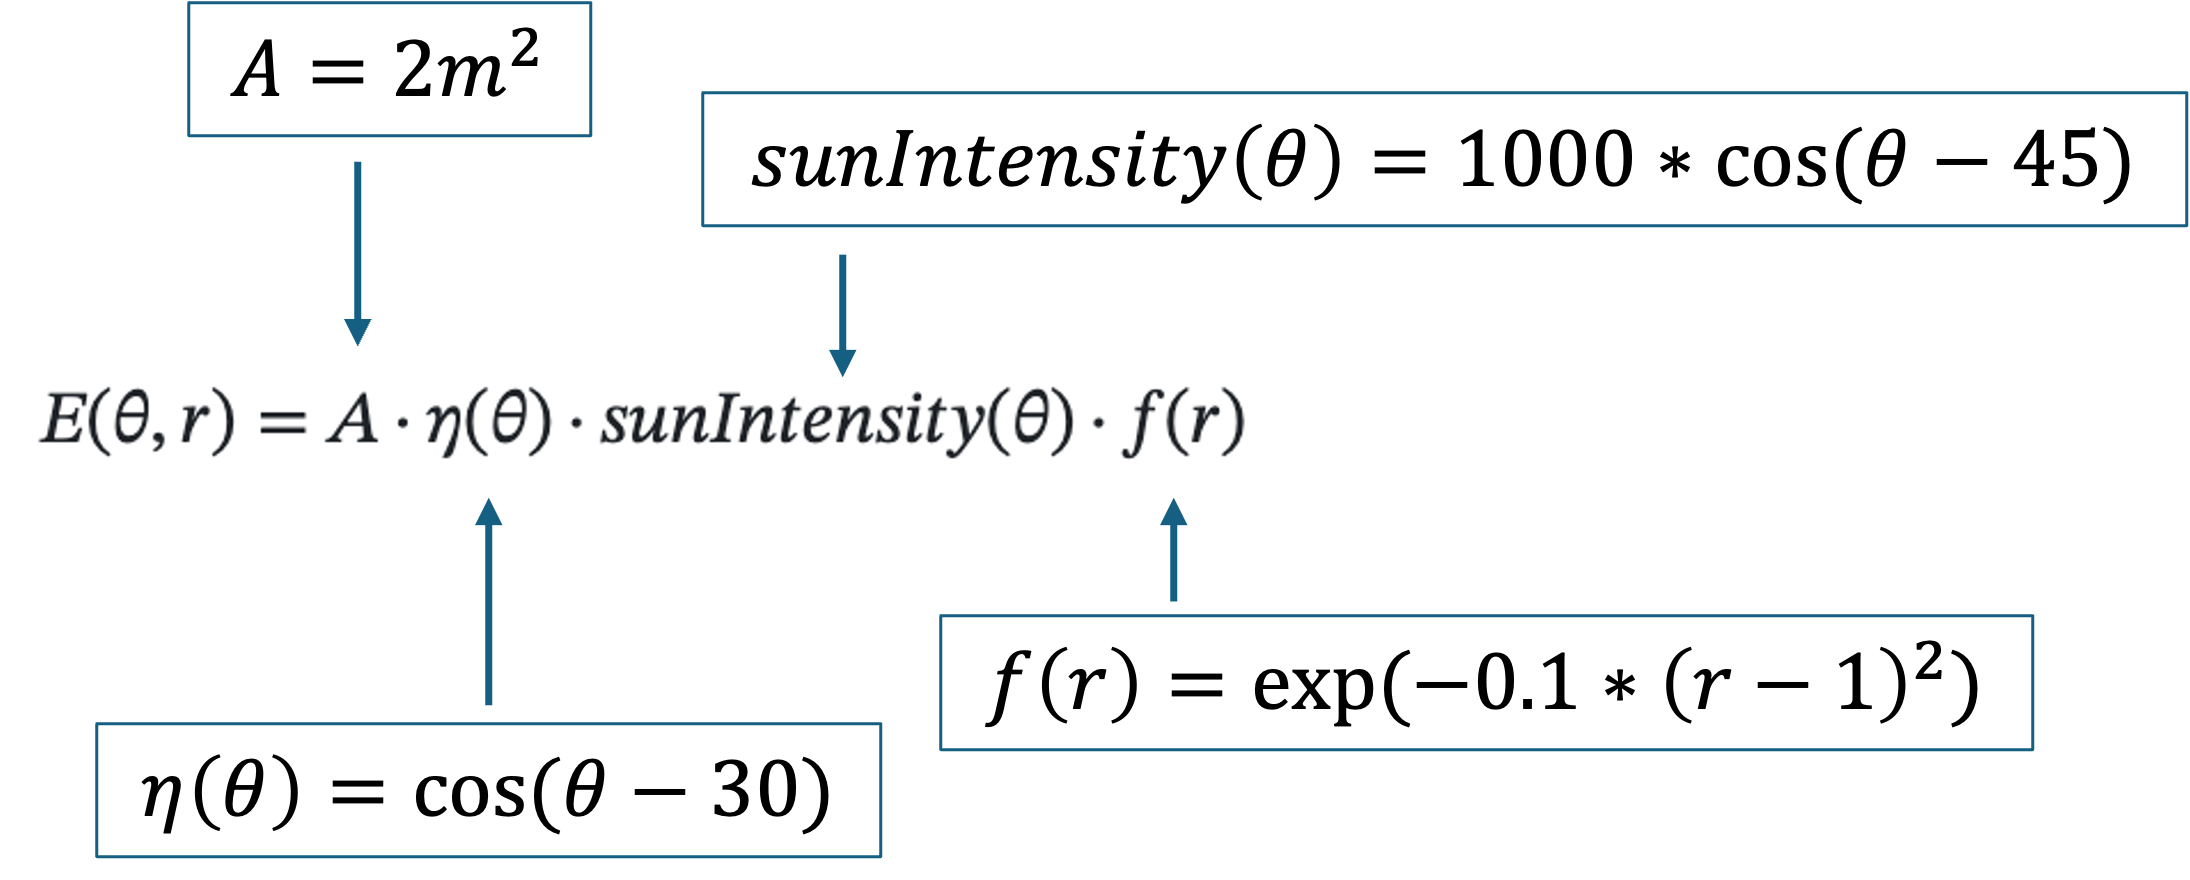

A = 2; % defined panel Area in m^2
theta = linspace(0,90,100); % inputs 100 different values evenly spaced from 0-90 degrees into the SunIntensity function and nu function
r = linspace(0.5,4,100); % inputs 100 different values evenly spaced from 0.5-4 ratio between length and width of the 2m^2 area
E = A * nu(theta) .* sunIntensity(theta) .* f(r) % Energy function with tilt angle and aspect ratio as the two variables

E = 1.0e+03 *

    1.1945    1.2285    1.2620    1.2951    1.3278    1.3598    1.3913    1.4221    1.4522    1.4815    1.5100    1.5376    1.5643    1.5900    1.6148    1.6384    1.6610    1.6824    1.7027    1.7218    1.7396    1.7561    1.7714    1.7853    1.7978    1.8090    1.8189    1.8273    1.8343    1.8398    1.8440    1.8467    1.8480    1.8479    1.8463    1.8433    1.8389    1.8331    1.8260    1.8175    1.8076    1.7964    1.7839    1.7702    1.7552    1.7391    1.7217    1.7033    1.6837    1.6631


% helper functions: f, nu, SunIntensity found in Current Folder

## Task 2: Implementing the Optimization Function

Use MATLAB's Optimization Toolbox to find the optimal tilt angle and aspect ratio that MAXIMIZE energy output. This MATLAB [doc page](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html) will be helpful.

% Step 1. Creating the optimization problem.
prob = optimproblem("Description","Energy Output", ...
    "ObjectiveSense", "maximize"); % uses built-in function of optimproblem to describe problem first. then create the objective sense telling MATLAB that we're maximizing energy.

% Step 2. Define the optimization variables
% MATLAB will try to optimize: 
% - theta (tilt angle), must stay between 0 and 90 degrees
% - r (aspect ratio), must stay between 0.5 and 4

theta = optimvar("theta", "LowerBound", 0, "UpperBound", 90); % tilt angle ranging from 0 to 90 degrees using built-in function of optimvar, creating an optimization variable 
r = optimvar("r", "LowerBound", 0.5, "UpperBound", 4); % aspect ratio ranging from 0.5 to 4 using built-in function optimvar creating an optimization variable 

% Step 3. Turning our energy function into an optimization problem MATLAB can cooperate with
% MATLAB can plug in different values for theta and r while solving the problem. converts the energy function to an optimization expression
energyExpr = fcn2optimexpr(@(theta,r)2*nu(theta)*sunIntensity(theta)*f(r),theta,r); % implement helper functions into optimization expression

% Step 4. setting the energy formula as the objective tells MATLAB what we want to maximize

prob.Objective = energyExpr; % optimize the energy expression defined in the last step

% Step 5. MATLAB Optimization requies a guess to start from:
     % Start searching from a tilt angle of 45 degrees
     % Start searching from an aspect ratio of 2
     x0.theta = 45; % initial guess of theta
     x0.r = 2; % initial guess of aspect ratio 

% Step 6. Solve the problem
[sol,fval] = solve(prob,x0) % Used the Optimization Toolbox function of "solve". Used inputs, such as the problem and objectives (theta and r) from initial guesses to obtain optimal values of tilt angle and r and the maximum output energy 


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
        r: 1.0000
    theta: 37.5000


fval = 1.9659e+03

show(prob) % displays the details of the optimization problem


  OptimizationProblem : Energy Output

	Solve for:
       r, theta

	maximize :
       arg1

       where:

           anonymousFunction1 = @(theta,r)2*nu(theta)*sunIntensity(theta)*f(r);
           arg1 = anonymousFunction1(theta, r);


	variable bounds:
       0.5 <= r <= 4

       0 <= theta <= 90



## Task 3: The Results.

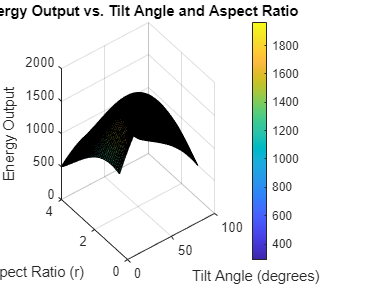

%% Task 3: Output the Results

% Step 1. Create a grid for our angles and ratios.
% We use the built-in meshgrid function to generate 2D arrays. This lets us 
% map out every possible combination of our tilt angle (theta) from 0 to 90 
% and our aspect ratio (r) from 0.5 to 4.
[theta, r] = meshgrid(0:0.5:90, 0.5:0.1:4);


% Step 2. Calculate the energy for every point on our grid.
% We define our area A as 2. Then, we use the dot operator (.*) for 
% element-wise multiplication so we can calculate the energy across our 
% entire theta and r matrices all at the exact same time.
A = 2; 
Energy = A .* nu(theta) .* sunIntensity(theta) .* f(r);


% Step 3. Draw our 3D surface plot.
% We use the built-in figure function to open a new blank window, and then 
% we use surf to stretch a 3D topographical surface over our theta, r, and 
% Energy data. We also add a colorbar to help us visualize the intensity.
figure;
surf(theta, r, Energy)
colorbar


% Step 4. Label our plot so we know what we're looking at.
% We use built-in labeling functions to give our graph a title and assign 
% the correct physical units to our x, y, and z axes.
title('Energy Output vs. Tilt Angle and Aspect Ratio')
xlabel('Tilt Angle (degrees)')
ylabel('Aspect Ratio (r)')
zlabel('Energy Output')



% Step 5. Find our maximum energy value and where it lives in our matrix.
% First, we flatten our 2D Energy matrix using Energy(:) so we can find the 
% absolute maximum value and its index location (idx). 
[max_Energy, idx] = max(Energy(:));

% Then, we use the built-in ind2sub function to translate that single index 
% back into specific row and column coordinates for our grid.
[row, col] = ind2sub(size(Energy), idx);

% Finally, we use those row and col coordinates to extract our optimal 
% tilt angle and aspect ratio from our original grids.
best_theta = theta(row, col);
best_r = r(row, col);


% Step 6. Print our final results to the command window.
% We use disp to create a clean header, and then we use fprintf to format 
% our optimal numbers so they display neatly to two decimal places (%.2f).
disp('--- Optimization Results ---')

--- Optimization Results ---


fprintf('Best tilt angle: %.2f degrees\n', best_theta)

Best tilt angle: 37.50 degrees


fprintf('Best aspect ratio: %.2f\n', best_r)

Best aspect ratio: 1.00


fprintf('Max energy output: %.2f\n', max_Energy)

Max energy output: 1965.93


## Interpretation of Results

**Results:**

The position of a solar cell that maximizes the amount of Energy converted from solar energy to electrical energy occurs when the tilt angle is 37.5 degrees. The ratio of the solar cells dimensions (length x width) that results in the maximum energy is 1.00. When both of these conditions are met, the solar cell will output the Maximum Amount of Energy Output possible in a constrained area of 2m^2. 

**Next Steps:**

One of the ways we would extend the project is applying the concepts to a physical lab by testing solar cells of different aspect ratios and different tilt angles at a constant time of day and recording the Energy converted using a voltmeter. 

Another way we would extend the project is to apply realistic constraints to the Energy function.The results we found currently would be applicable in ideal climate (peak solar input, no shade/clouds). Since, Energy converted depends on the amount of solar energy input on the solar cell, Energy input varies depending on: Time of day, climate (clouds, rain, season, etc.), Latitude and Longitude of the solar cell (Location on Earth). Which in turn, affects the Energy output (converted by solar cell). The next steps would be to include these real world factors and testing the optimal position based on these factors.